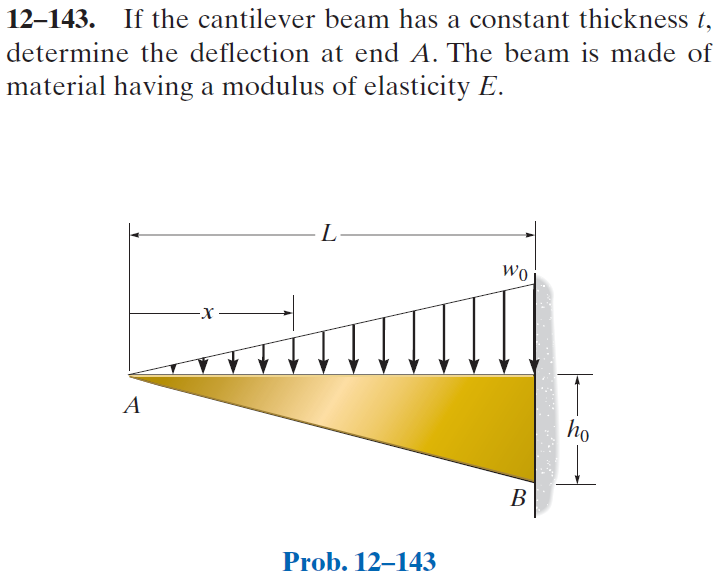

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-143RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-143RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
L = sym('L');
w1 = findpoly(1, 'thru', [0 0], [L -wo]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('reaction', 'moment', 'Mb', L);
b = b.add('distributed', 'force', w1, [0 L]);

# section properties

ho = sym('ho');
t = sym('t');
h = findpoly(1, 'thru', [0 0], [L ho]);
b.I = t*h^3/12;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = -\frac{L^{2}\,\mathrm{wo}\,{\left(L-x\right)}^{2}}{\text{E}\,{\mathrm{ho}}^{3}\,t}$$

dy

$$dy(x) = \frac{2\,L^{2}\,\mathrm{wo}\,\left(L-x\right)}{\text{E}\,{\mathrm{ho}}^{3}\,t}$$

m

$$m(x) = -\frac{\mathrm{wo}\,x^{3}}{6\,L}$$

v

$$v(x) = -\frac{\mathrm{wo}\,x^{2}}{2\,L}$$

w

$$w(x) = -\frac{\mathrm{wo}\,x}{L}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Mb} & -\frac{L^{2}\,\mathrm{wo}}{6}\\ \mathrm{Rb} & \frac{L\,\mathrm{wo}}{2} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

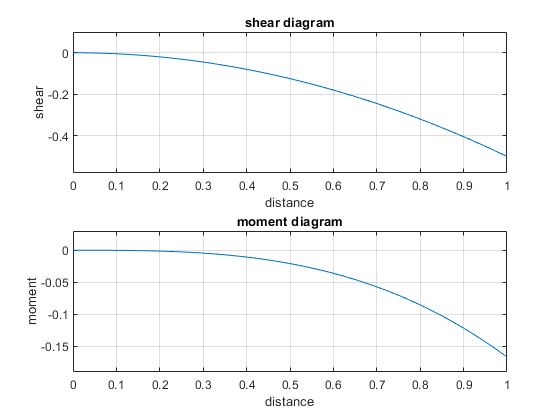

beam.shear_moment(m, v, [0 1], [wo L], 1);
subplot(2,1,1);
axis([0 1 -0.58 0.1]);
subplot(2,1,2);
axis([0 1 -0.19 0.03]);

# deflection at A

yA = y(0) %#ok<NASGU> 

$$yA = -\frac{L^{4}\,\mathrm{wo}}{\text{E}\,{\mathrm{ho}}^{3}\,t}$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear yA;
clear old_assum;